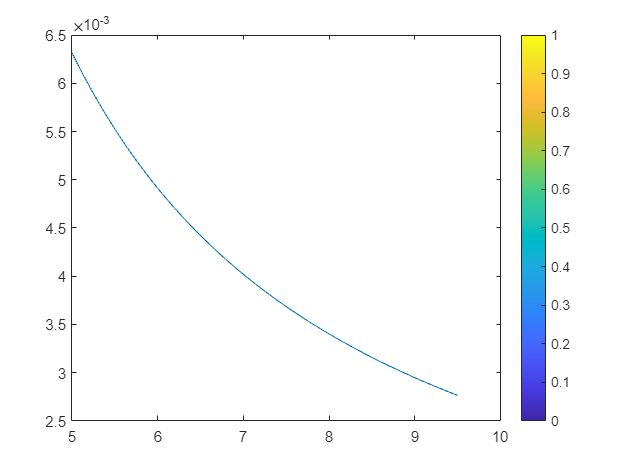

clc;
clear ;
a=0;
b=15;
g = 9.81;
of = 1.5;
V = 21.68 ;
iteration = 30;
d1 = zeros (1,90);
i = 1;
for os = 5 : 0.05 : 9.5
f =@(d) sqrt((3*g*d)*(os-of)/of) - 21.69;
d1(1,i) = secant(f,a,b,iteration);
i = i + 1;
end
% ---------
a=0;
b=100;
iteration = 50;
d2 = zeros(1,90);
i = 1;
for os = 5 : 0.05 : 9.5
f =@(x) sqrt((3*g*x)*(os-of)/of) - 21.69;
d2(1,i) = half(f,a,b,iteration);
i = i + 1;
end
% ---------
D = @(s)(of*V^2)/(3*g*(s - of));
d3 = zeros (1,90);
i = 1;
svalues = [];
for s = 5 : 0.05 : 9.5
    format long ;
    d3(1,i) = D(s);
    i = i + 1;
    svalues = [svalues s];
end

error_Inplace = abs(d3 - d1);
error_HalfRoot = abs(d2 - d1);
plot(svalues,error_Inplace);

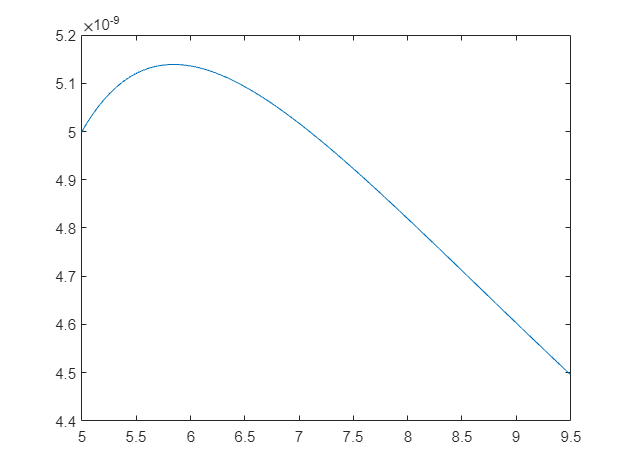

plot(svalues,error_HalfRoot);

function[output] = secant(f,a,b,iteration)
    for i = 1 : iteration
    ai = a;
    bi = b;
    ri = (ai*(eval(subs(f,bi))) - bi*(eval(subs(f,ai))))/((eval(subs(f,bi))) - (eval(subs(f,ai))));
    if(eval(subs(f,ri))==0)
        break;
    elseif ((eval(subs(f,ri))*eval(subs(f,ai)))>0)
       a = ri;
    else
       b = ri;  
    end
    end
    format long;
    output = ri;
end

function[output] = half(f,a,b,iteration)
    for i = 1 : iteration
    ai = a;
    bi = b;
    ri = (ai + bi)/2;
    if(eval(subs(f,ri))==0)
        break;
    elseif ((eval(subs(f,ri))*eval(subs(f,ai)))>0)
       a = ri;
    else
       b = ri;  
    end
    end
    format long;
    output = ri;
end



